# problem 6

## beam

u = symunit;
x = sym('x');
E = sym('E');
I = sym('I');

old_assum = assumptions;
clearassum;

b = beam; %(kip,ft)
b = b.add('reaction', 'force', 'Ra', 0);
b = b.add('reaction', 'force', 'Rd', 9*u.m);
b = b.add('applied', 'force', -55*u.kN, 3*u.m);
b = b.add('distributed', 'force', -15*u.kN/u.m, [6 9]*u.m);
b.L = 9*u.m;

## elastic curve

[y(x,E,I) dy(x,E,I) m v w r] = b.elastic_curve(x, 'factor'); %#ok
y

$$y(x, E, I) = \left\{ \begin{array}{cl} -\frac{5\,x\,\left(5337\,m^{2}-106\,x^{2}\right)}{72\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq 3\,m\\ -\frac{5\,\left(26\,x^{3}-1188\,x^{2}\,m+8901\,x\,m^{2}-3564\,m^{3}\right)}{72\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(3\,m,6\,m\right]\\ \frac{5\,\left(x-9\,m\right)\,\left(-9\,x^{3}+109\,x^{2}\,m+225\,x\,m^{2}+900\,m^{3}\right)}{72\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }6\,m<x \end{array}\right.$$

dy

$$dy(x, E, I) = \left\{ \begin{array}{cl} -\frac{5\,\left(1779\,m^{2}-106\,x^{2}\right)}{24\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\leq 3\,m\\ -\frac{5\,\left(26\,x^{2}-792\,x\,m+2967\,m^{2}\right)}{24\,\text{E}\,\text{I}}\,\mathrm{kN} & \text{ if }x\in \left(3\,m,6\,m\right]\\ -\frac{5\,\left(12\,x^{3}-190\,x^{2}\,m+504\,x\,m^{2}+375\,m^{3}\right)}{24\,\text{E}\,\text{I}}\,\frac{\mathrm{kN}}{m} & \text{ if }6\,m<x \end{array}\right.$$

m

$$m(x) = \left\{ \begin{array}{cl} \frac{265\,x}{6}\,\mathrm{kN} & \text{ if }x\leq 3\,m\\ -\frac{5\,\left(13\,x-198\,m\right)}{6}\,\mathrm{kN} & \text{ if }x\in \left(3\,m,6\,m\right)\\ -\frac{5\,\left(x-9\,m\right)\,\left(9\,x-14\,m\right)}{6}\,\frac{\mathrm{kN}}{m} & \text{ if }6\,m\leq x \end{array}\right.$$

v

$$v(x) = \left\{ \begin{array}{cl} \frac{265}{6}\,\mathrm{kN} & \text{ if }x\leq 3\,m\\ -\frac{65}{6}\,\mathrm{kN} & \text{ if }x\in \left(3\,m,6\,m\right)\\ -\frac{5\,\left(18\,x-95\,m\right)}{6}\,\frac{\mathrm{kN}}{m} & \text{ if }6\,m\leq x \end{array}\right.$$

w

$$w(x) = \left\{ \begin{array}{cl} 0 & \text{ if }x<6\,m\\ -15\,\frac{\mathrm{kN}}{m} & \text{ if }6\,m\leq x \end{array}\right.$$

## reactions

Ra = vpa(r.Ra, 4) %#ok

$$Ra = 44.17\,\mathrm{kN}$$

Rd = vpa(r.Rd, 4) %#ok

$$Rd = 55.83\,\mathrm{kN}$$

## shear and moment diagrams

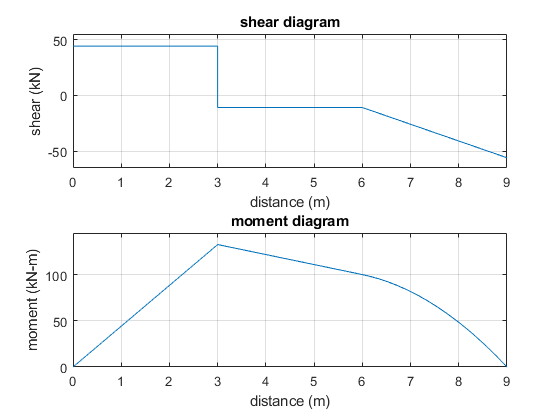

beam.shear_moment(m, v, [0 9], {'kN' 'm'});
subplot(2,1,1);
axis([0 9 -65 55]);
subplot(2,1,2);
axis([0 9 0 145]);

## clean up

setassum(old_assum);
clear old_assum Ra Rd;